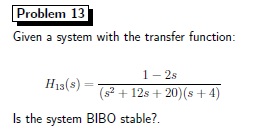

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



H=(1-2*s)/((s^2+12*s+20)*(s+4))

H =
 
          -2 s + 1
  ------------------------
  s^3 + 16 s^2 + 68 s + 80
 
Continuous-time transfer function.




H=minreal(zpk(H))  %zero pole gain model to see immediately the poles(zeros of denominator) and the zeros

H =
 
      -2 (s-0.5)
  ------------------
  (s+10) (s+4) (s+2)
 
Continuous-time zero/pole/gain model.



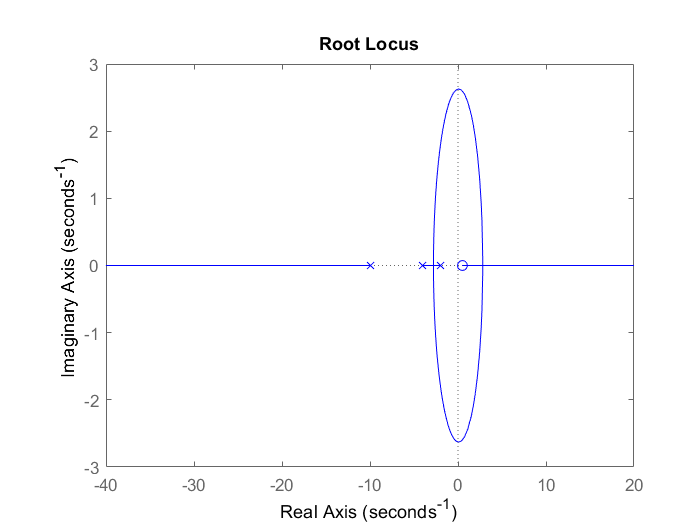

rlocus(H,'b')


isstable(H)

ans = logical
   1


eig(H)

ans =   -10.0000
   -4.0000
   -2.0000


The eigenvalues are all negative so the sistem is BIBO stable